# PV Orientation

clear all;
close all;

## Grundgerüst

%Umwandlung von dem Abgabedatum
%datum = datetime('2024-10-17');
%doy = day(datum, "dayofyear");
doy= 1:1:365;
% Berechne delta in Grad
delta = 23.45 * sind((360/365) * (doy + 284));
whatDay = 172;
% Zeit
t_h= 0.5:0.5:24;
t_j = 1:1:365;
% Standortbreite in Grad für IBK
phi = 47.27;
P_Null = 200; %[W/m²]
P_all = 0;

% Berechne den Winkel alpha für verschiedene Stunden t
% Alpha = Höhenwinkel
alpha = @(t) asind((sind(phi) * sind(delta(whatDay))) + (cosd(phi) * cosd(delta(whatDay)) * cosd(15*(t - 12))));
alpha_values_h = alpha(t_h)

alpha_values_h =   -18.9573  -17.9976  -16.4276  -14.2876  -11.6276   -8.5030   -4.9704   -1.0851    3.1008    7.5389   12.1846   16.9966   21.9358   26.9640   32.0417   37.1257   42.1652   47.0956   51.8299   56.2446   60.1616   63.3299   65.4352   66.1798   65.4352   63.3299   60.1616   56.2446   51.8299   47.0956   42.1652   37.1257   32.0417   26.9640   21.9358   16.9966   12.1846    7.5389    3.1008   -1.0851   -4.9704   -8.5030  -11.6276  -14.2876  -16.4276  -17.9976  -18.9573  -19.2802


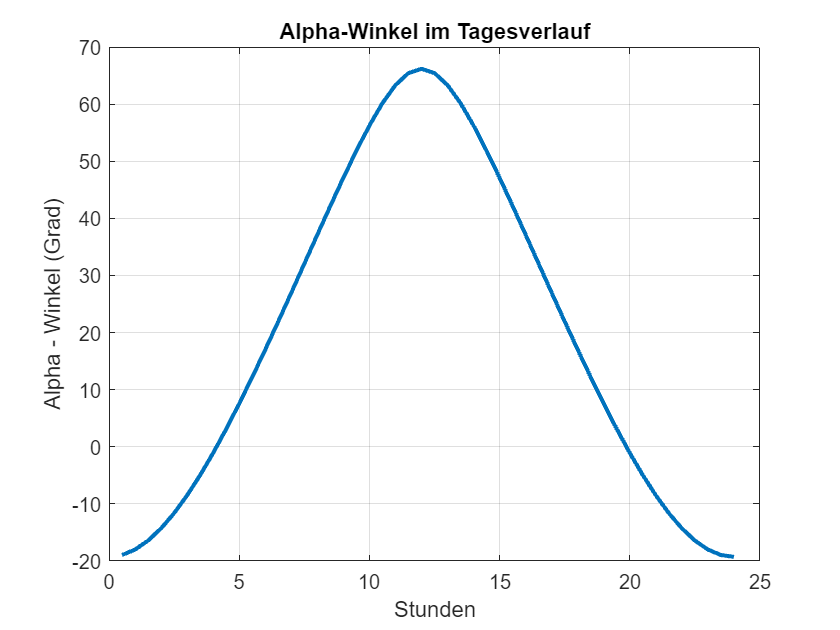

figure;
plot(t_h, alpha_values_h, 'LineWidth', 2);
xlabel('Stunden');
ylabel('Alpha - Winkel (Grad)');
title('Alpha-Winkel im Tagesverlauf');
grid on;

% %Methode2
% for t = 1:24
%      alpha(t) = asind((sind(phi) * sind(delta)) + (cosd(phi) * cosd(delta) * cosd(15*(t - 12))));
% end


%Sonnenaufgang
time_up = -(acosd(-tand(phi)*tand(delta)) / 15) + 12

time_up =     7.8248    7.8171    7.8087    7.7996    7.7900    7.7797    7.7689    7.7574    7.7454    7.7328    7.7197    7.7059    7.6917    7.6769    7.6616    7.6457    7.6294    7.6126    7.5953    7.5775    7.5593    7.5406    7.5215    7.5020    7.4820    7.4617    7.4410    7.4199    7.3984    7.3766    7.3544    7.3319    7.3091    7.2860    7.2625    7.2388    7.2148    7.1905    7.1660    7.1412    7.1161    7.0909    7.0654    7.0397    7.0137    6.9876    6.9613    6.9348    6.9082    6.8813



time_up_dateformat = datestr( time_up/24, "HH:MM:SS");

%Sonnenuntergang
time_down = (acosd(-tand(phi)*tand(delta)) / 15) + 12;
time_down_dateformat = datestr( time_down/24, "HH:MM:SS");

%Uptime Sonne
% Umwandlung in duration-Objekte
decimalHours = time_down-time_up;

% Umwandlung in ein duration-Objekt
timeDuration = hours(decimalHours);

% Festlegen des Formats auf "hh:mm:ss"
timeDuration.Format = 'hh:mm:ss';

% Ausgabe
[maxDuration, pos_max]= max(timeDuration(:))

maxDuration = duration
   15:44:03


pos_max = 172

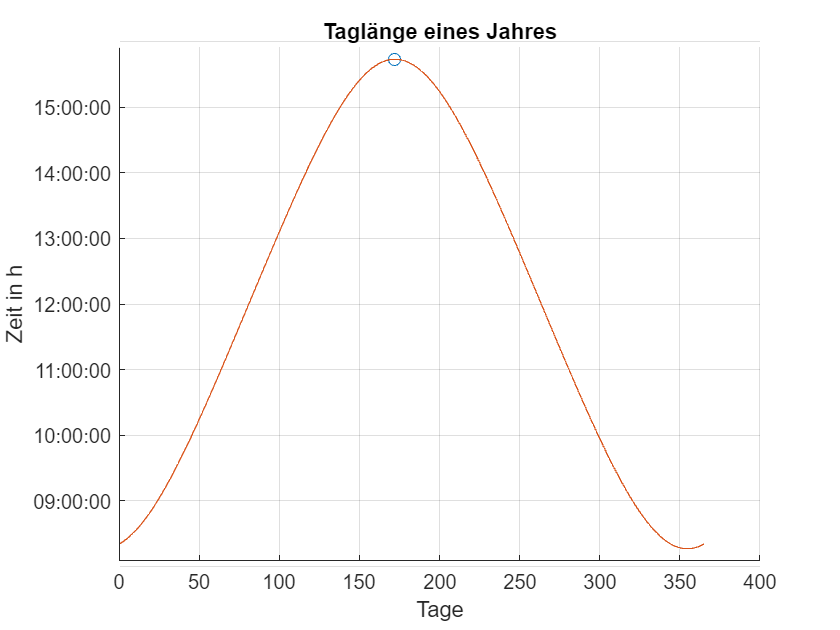

figure;
hold on
plot(pos_max,maxDuration,'o');
plot(t_j,timeDuration);
xlabel("Tage");
ylabel("Zeit in h")
title("Taglänge eines Jahres")
grid on;
hold off;

%Azimut
azimut_winkel = @(t,alpha)  real(acosd((sind(delta(whatDay))-sind(alpha(t)).*sind(phi)) ./ (cosd(alpha(t)).*cosd(phi))));
azimut_wikel_value_h = azimut_winkel(t_h,alpha)

azimut_wikel_value_h =     7.2739   14.4573   21.4703   28.2517   34.7631   40.9891   46.9348   52.6215   58.0834   63.3644   68.5164   73.5991   78.6809   83.8421   89.1796   94.8148  100.9044  107.6568  115.3517  124.3576  135.1216  148.0621  163.2592  180.0000  163.2592  148.0621  135.1216  124.3576  115.3517  107.6568  100.9044   94.8148   89.1796   83.8421   78.6809   73.5991   68.5164   63.3644   58.0834   52.6215   46.9348   40.9891   34.7631   28.2517   21.4703   14.4573    7.2739    0.0000


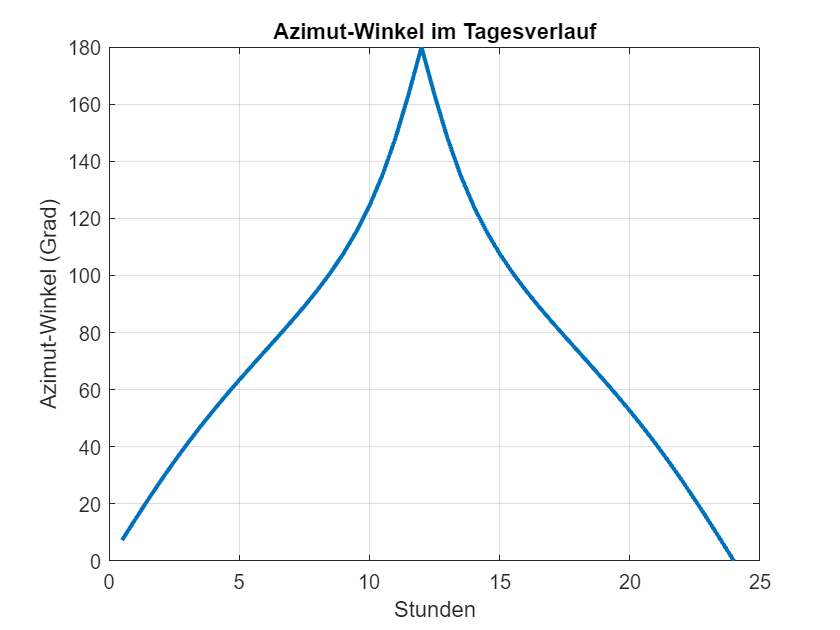

figure;
plot(t_h, azimut_wikel_value_h, 'LineWidth', 2);
xlabel('Stunden');
ylabel('Azimut-Winkel (Grad)');
title('Azimut-Winkel im Tagesverlauf');
grid on;

%Vektor zur Sonne, x=Höhenwinkel; z=Azimutwinkel; y=0
n = [0,0,1];    %Vektor PV-Modul
x = cosd(alpha_values_h(:,24)) .* sind(azimut_wikel_value_h(:,24));
y = cosd(alpha_values_h(:,24)) .* cosd(azimut_wikel_value_h(:,24));
z = sind(alpha_values_h(:,24));
s = [x;y;z]'     %Vektor Sonne

s =          0   -0.4039    0.9148


P= P_Null * dot(n,s);

P = 182.9634

n = [0,0,1]; 
for i= 1:24
    x = cosd(alpha_values_h(:,i)) .* sind(azimut_wikel_value_h(:,i));
    y = cosd(alpha_values_h(:,i)) .* cosd(azimut_wikel_value_h(:,i));
    z = sind(alpha_values_h(:,i));
    s = [x;y;z]';     %Vektor Sonne
    P= P_Null * dot(n,s);
    if P > 0
        P_all= P_all+P_Null;
    end
end
P_all

P_all = 3200